### Effectiveness estimation routine

Import the data from the data file

ismac = 1;
if ismac
    p = parselog('/Users/tomasodeponti/Desktop/logs_sd_1403/80_01_07__20_22_44_SD.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\flight_data\log_sd_2203\15to45\80_01_08__16_10_47_SD.data');%('C:\Users\Tomaso\Desktop\flight_data\16_51_51_cyberzoo\16_51_51_cyberzoo\80_01_08__17_50_59_SD.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end
ac_data = p.aircrafts.data;

Perform a frequency analysis of the angular acceleration signal to identify the noisy frequency bands.

la_x = ac_data.EFF_FULL_INDI.body_accel_x - mean(ac_data.EFF_FULL_INDI.body_accel_x);
la_y = ac_data.EFF_FULL_INDI.body_accel_y - mean(ac_data.EFF_FULL_INDI.body_accel_y);
la_z = ac_data.EFF_FULL_INDI.body_accel_z - mean(ac_data.EFF_FULL_INDI.body_accel_z);

y_x = fft(la_x);
y_y = fft(la_y);
y_z = fft(la_z);

n = length(la_x);          % number of samples
fs = get_sf(ac_data.EFF_FULL_INDI.timestamp);
f = (0:n-1)*(fs/n);     % frequency range
power_x = abs(y_x).^2/n;    % power of the DFT
power_y = abs(y_y).^2/n;
power_z = abs(y_z).^2/n;
power   = power_x + power_y + power_z;

figure(101)
subplot(4,1,1)
plot(f,power_x)
xlabel('Frequency')
ylabel('Power')
title('X')

subplot(4,1,2)
plot(f,power_y)
xlabel('Frequency')
ylabel('Power')
title('Y')

subplot(4,1,3)
plot(f,power_z)
xlabel('Frequency')
ylabel('Power')
title('Z')

subplot(4,1,4)
plot(f,power)
xlabel('Frequency')
ylabel('Power')
title('Total')
f_filter = 10;%1.45;%3;

Prepare acceleration signal

t  = ac_data.EFF_FULL_INDI.timestamp;
p  = ac_data.EFF_FULL_INDI.angular_rate_p;
q  = ac_data.EFF_FULL_INDI.angular_rate_q;
r  = ac_data.EFF_FULL_INDI.angular_rate_r;
ax = ac_data.EFF_FULL_INDI.body_accel_x ;
ay = ac_data.EFF_FULL_INDI.body_accel_y ;
az = ac_data.EFF_FULL_INDI.body_accel_z ;

sf = get_sf(t);
order = 4;
[b,a] = butter(order,f_filter/(sf/2),'low')  ;

a_p = low_butter(diff_scaled(p,t),f_filter,sf,0,order);
a_q = low_butter(diff_scaled(q,t),f_filter,sf,0,order);
a_r = low_butter(diff_scaled(r,t),f_filter,sf,0,order);
ax_f = low_butter(ax,f_filter,sf,0,order);
ay_f = low_butter(ay,f_filter,sf,0,order);
az_f = low_butter(az,f_filter,sf,0,order);
acc = [a_p,a_q,a_r];
acc_l = [ax_f,ay_f,az_f];

figure(70)
clf
plot(t(2:end),a_p)
hold on
plot(t(2:end),diff_scaled(p,t))
plot(t(2:end),a_p)
legend("filt acc","original acc","sync acc")

Prepare actuator command signal 0-9600

act_names = ["Motor Front","Motor Right","Motor Back","Motor Left","Aileron Left", "Aileron Right","Elevator","Rudder","Push Motor","Rot Mech"];
m_d       = ["Motor Front G2","Motor Right G2","Motor Back G2","Motor Left G2"];
act = cellfun(@(S) sscanf(S, '%f,').', ac_data.EFF_FULL_INDI.u, 'Uniform', 0);
act = cell2mat(act);
d_cv = cellfun(@(S) sscanf(S, '%f,').', ac_data.EFF_FULL_INDI.current_doublet_values, 'Uniform', 0);
d_cv = cell2mat(d_cv);

pwm_as = [1100,1900];
pwm_mot = [1000,2000];
pprz_as = [-9600,9600];
pprz_mot = [0,9600];

rate_lim = 1230000;
fo_mot = 24.5;%6;%24.5; % rad/s
fo_as  = 52.8;  %       % rad/s
synchronous_filtering = 1;
if synchronous_filtering
    act1 = low_butter(act(:,1),f_filter,sf,0,order);
    act2 = low_butter(act(:,2),f_filter,sf,0,order);
    act3 = low_butter(act(:,3),f_filter,sf,0,order);
    act4 = low_butter(act(:,4),f_filter,sf,0,order);
    act5 = low_butter(act(:,5),f_filter,sf,0,order);
    act6 = low_butter(act(:,6),f_filter,sf,0,order);
    act7 = low_butter(act(:,7),f_filter,sf,0,order);
    act8 = low_butter(act(:,8),f_filter,sf,0,order);
    m1 = pwm2pprz(pp_limiter(act1,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    m2 = pwm2pprz(pp_limiter(act2,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    m3 = pwm2pprz(pp_limiter(act3,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    m4 = pwm2pprz(pp_limiter(act4,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    as1 = pwm2pprz(pp_limiter(act5,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);
    as2 = pwm2pprz(pp_limiter(act6,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);
    as3 = pwm2pprz(pp_limiter(act7,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);
    as4 = pwm2pprz(pp_limiter(act8,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);

else
    m1 = pwm2pprz(pp_limiter(act(:,1),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    m2 = pwm2pprz(pp_limiter(act(:,2),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    m3 = pwm2pprz(pp_limiter(act(:,3),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    m4 = pwm2pprz(pp_limiter(act(:,4),pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf),pwm_mot,pprz_mot);
    as1 = pwm2pprz(pp_limiter(act(:,5),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);
    as2 = pwm2pprz(pp_limiter(act(:,6),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);
    as3 = pwm2pprz(pp_limiter(act(:,7),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);
    as4 = pwm2pprz(pp_limiter(act(:,8),pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf),pwm_as,pprz_as);
end

m1_d = [0;diff_scaled(m1,t)];
m2_d = [0;diff_scaled(m2,t)];
m3_d = [0;diff_scaled(m3,t)];
m4_d = [0;diff_scaled(m4,t)];


pf = low_butter(p,f_filter,sf,0,order);
qf = low_butter(q,f_filter,sf,0,order);
rf = low_butter(r,f_filter,sf,0,order);

damping = 0;
quad_mode = 1;
augment = 1;
act_aug = [m1,m2,m3,m4];
act_yaw = [m1,m2,m3,m4,m1_d,m2_d,m3_d,m4_d];
if augment
    act_aug = [act_aug,ones(size(m1))]
    act_yaw = [act_yaw,ones(size(m1))]
elseif damping
    act_aug = [act_aug,pf,qf,rf];
elseif ~quad_mode
    act_aug = [act_aug(:,1:4),as1,as2,as3,as4,act_aug(:,5:end)];
end

act_aug = 	1.0e+03 *

         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010
         0         0         0         0    0.0010


act_yaw = 	1.0e+04 *

         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001
         0         0         0         0         0         0         0         0    0.0001


### Now perform the effectiveness estimation during the doublets meneouvers

Select only timestamps where doublets were performed to estimate the effectiveness of the actuators.

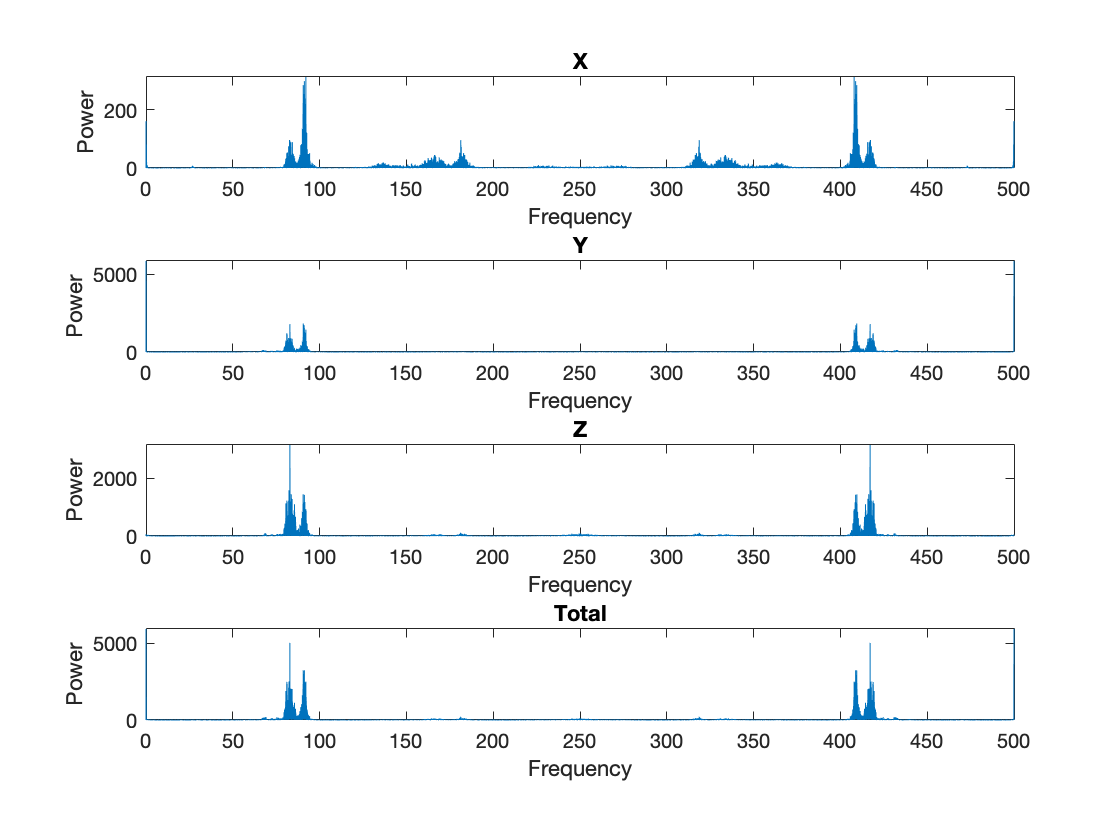

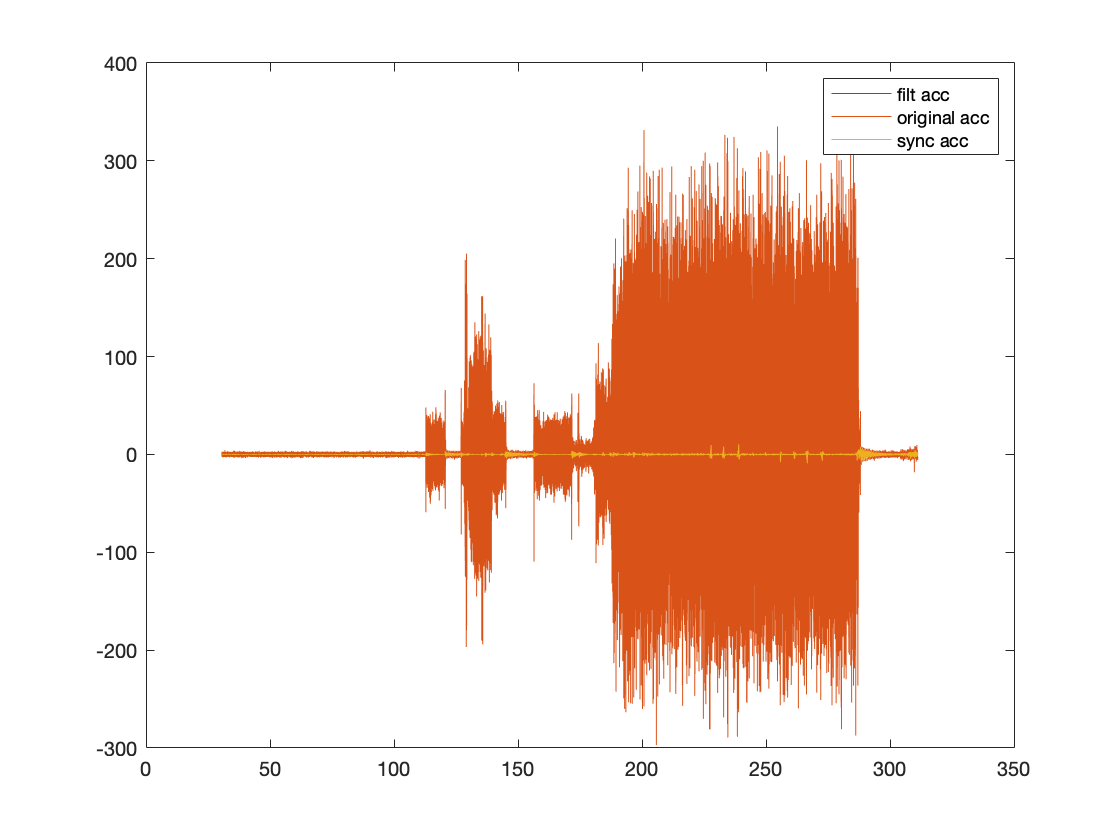

Estimation of effectiveness of actuator Motor Front 


    "ACT"       "-0.000673885"    "0.00190738"    "0.000348163"
    "OFFSET"    "4.91225"         "-14.1329"      "-2.5592"    



Estimation of effectiveness of actuator Motor Front 


    "ACT"       "-0.000703403"    "0.00219555"    "0.00049833"
    "OFFSET"    "5.27982"         "-16.4353"      "-3.70511"  



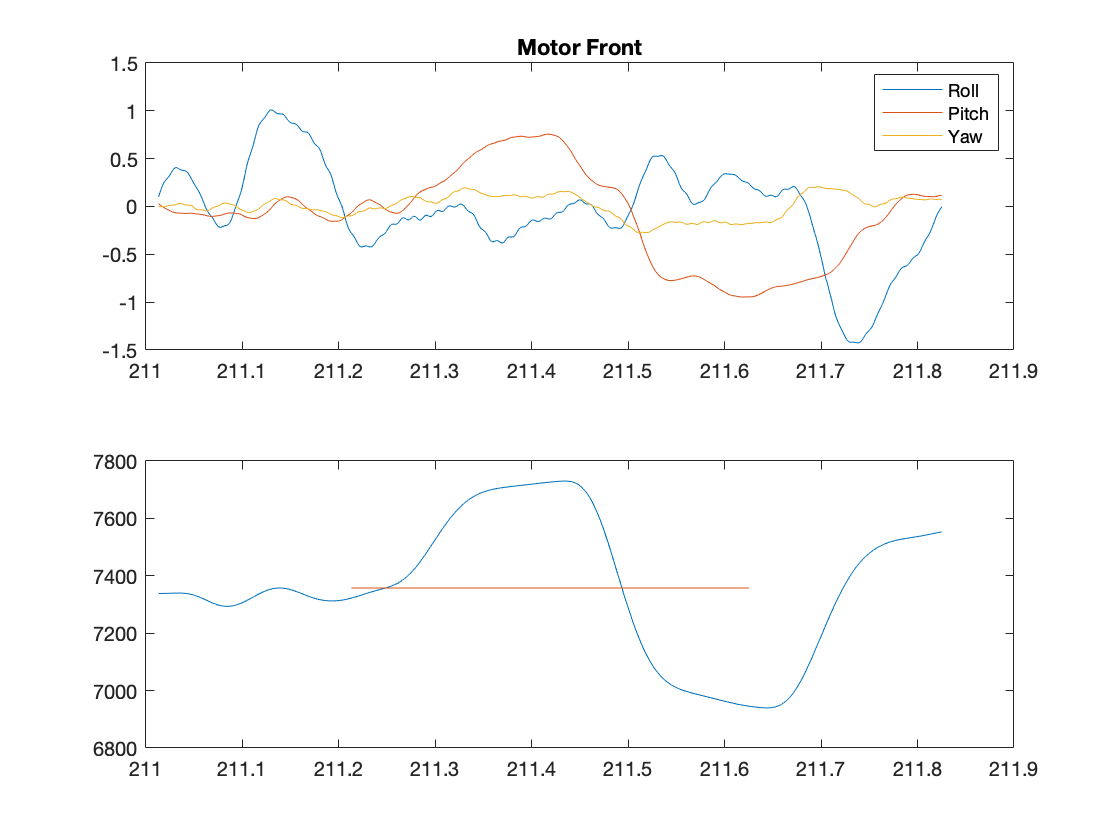

Estimation of effectiveness of actuator Motor Front 


    "ACT"       "-0.000438833"    "0.00251793"    "0.000451113"
    "OFFSET"    "3.24831"         "-18.8131"      "-3.35232"   



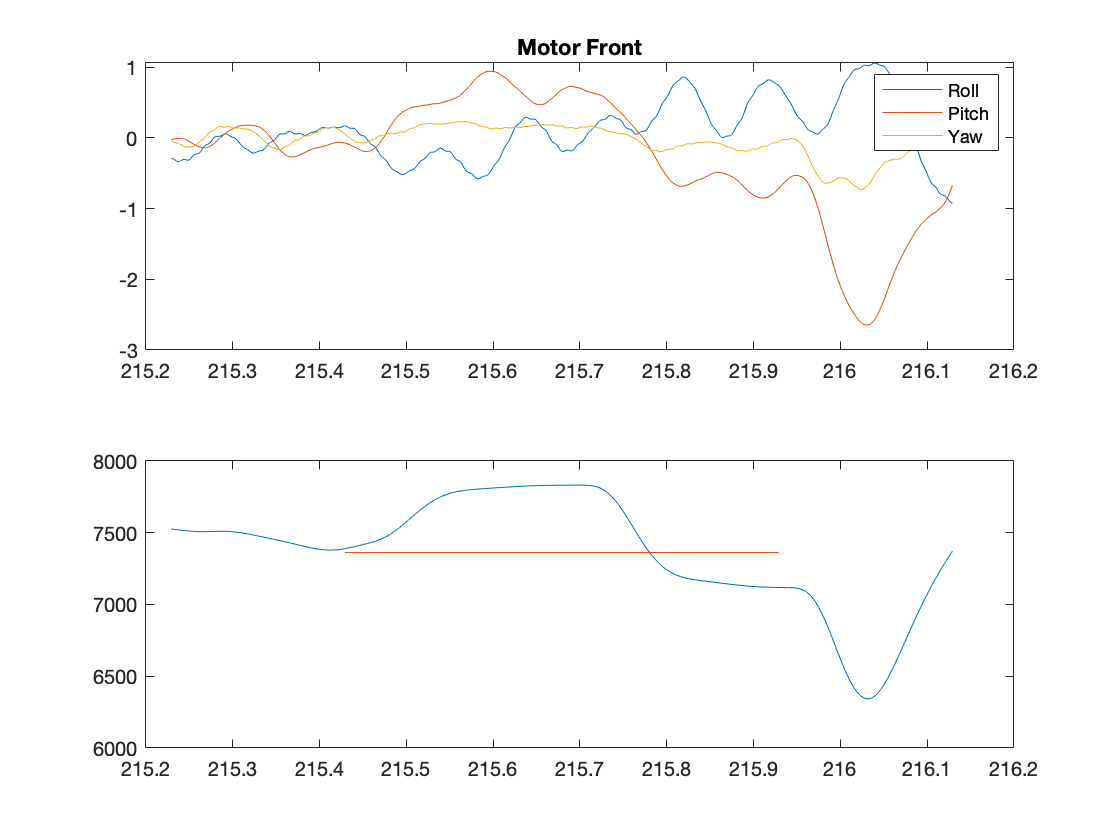

Estimation of effectiveness of actuator Motor Right 


    "ACT"       "-0.00909437"    "-0.000329516"    "-0.000517739"
    "OFFSET"    "62.4097"        "2.27619"         "3.53341"     



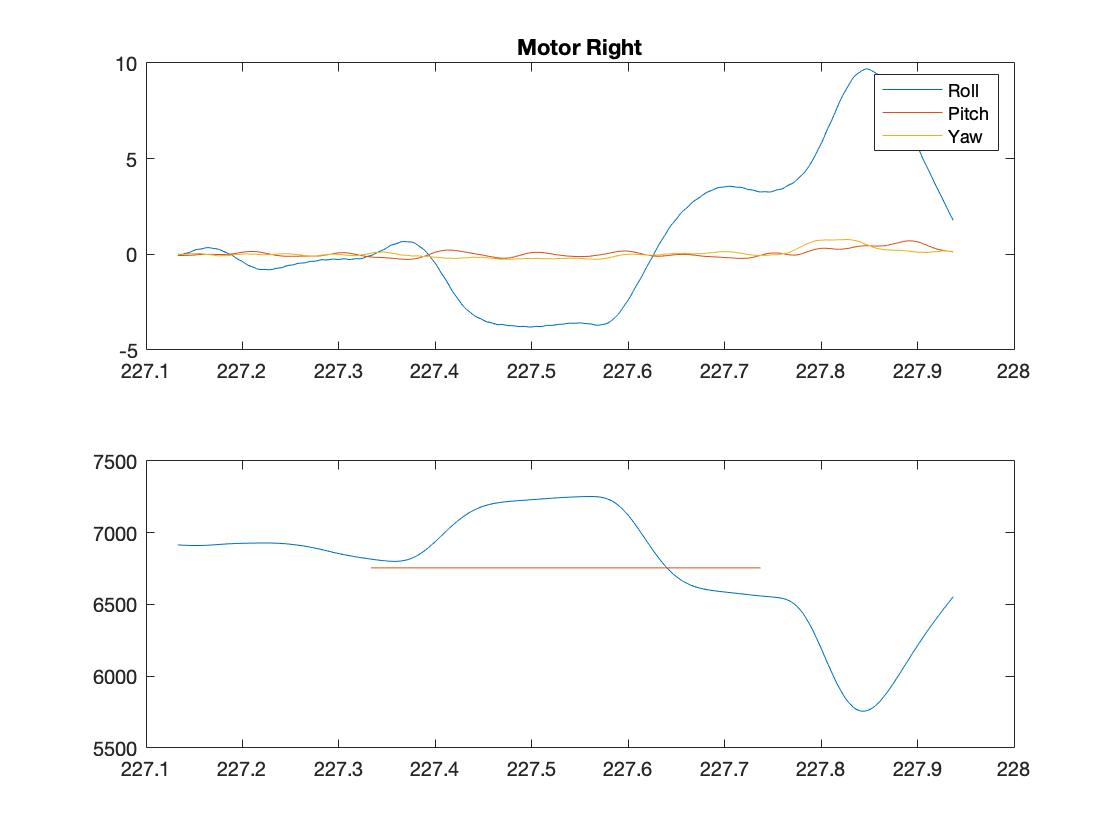

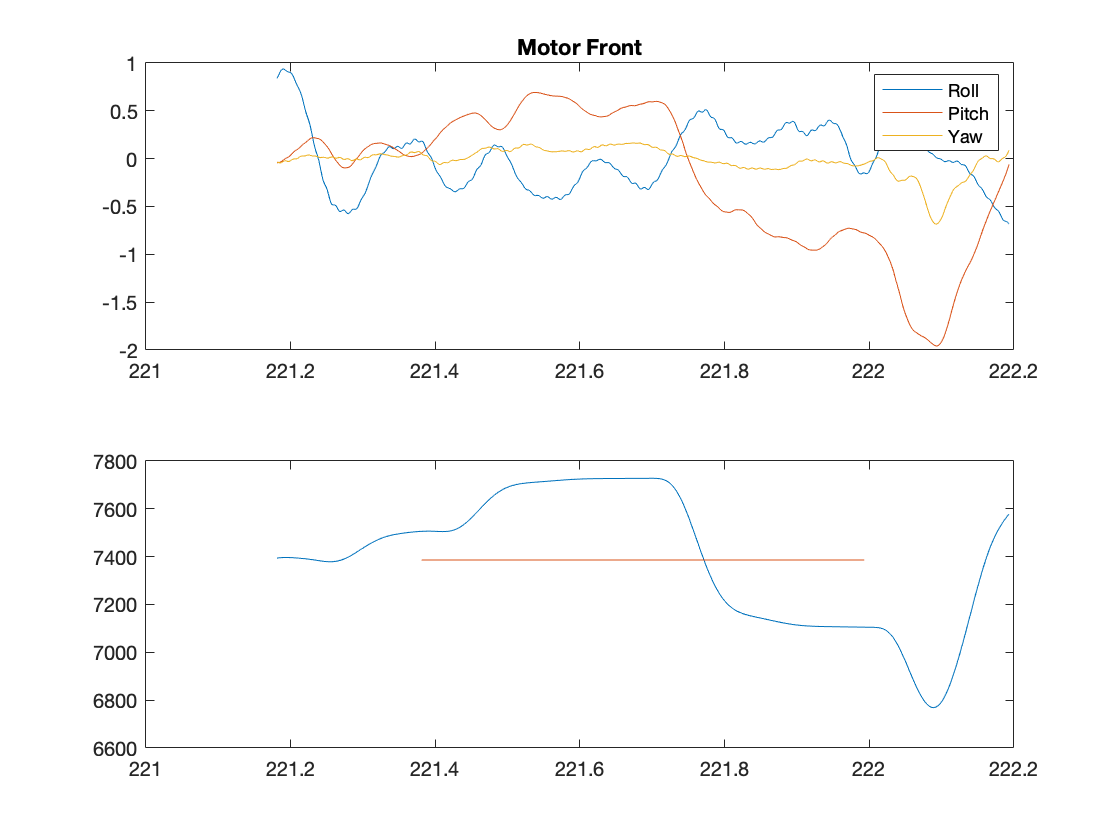

Estimation of effectiveness of actuator Motor Right 


    "ACT"       "-0.00826794"    "0.000193156"    "-0.000436673"
    "OFFSET"    "56.6653"        "-1.30737"       "2.98234"     



Estimation of effectiveness of actuator Motor Right 


    "ACT"       "-0.0123474"    "0.00108321"    "-0.00022783"
    "OFFSET"    "83.6735"       "-7.34675"      "1.54282"    



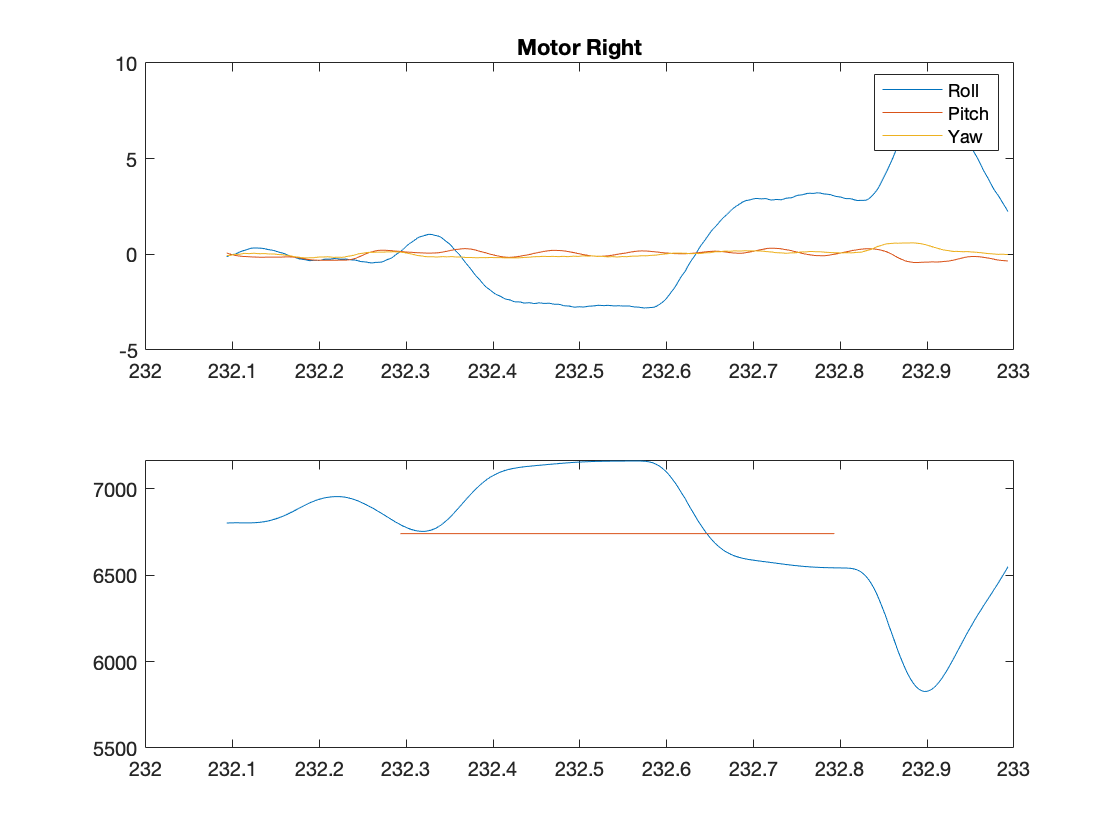

Estimation of effectiveness of actuator Motor Back 


    "ACT"       "-0.000837366"    "-0.00223928"    "0.000106333"
    "OFFSET"    "6.28713"         "16.6414"        "-0.784509"  



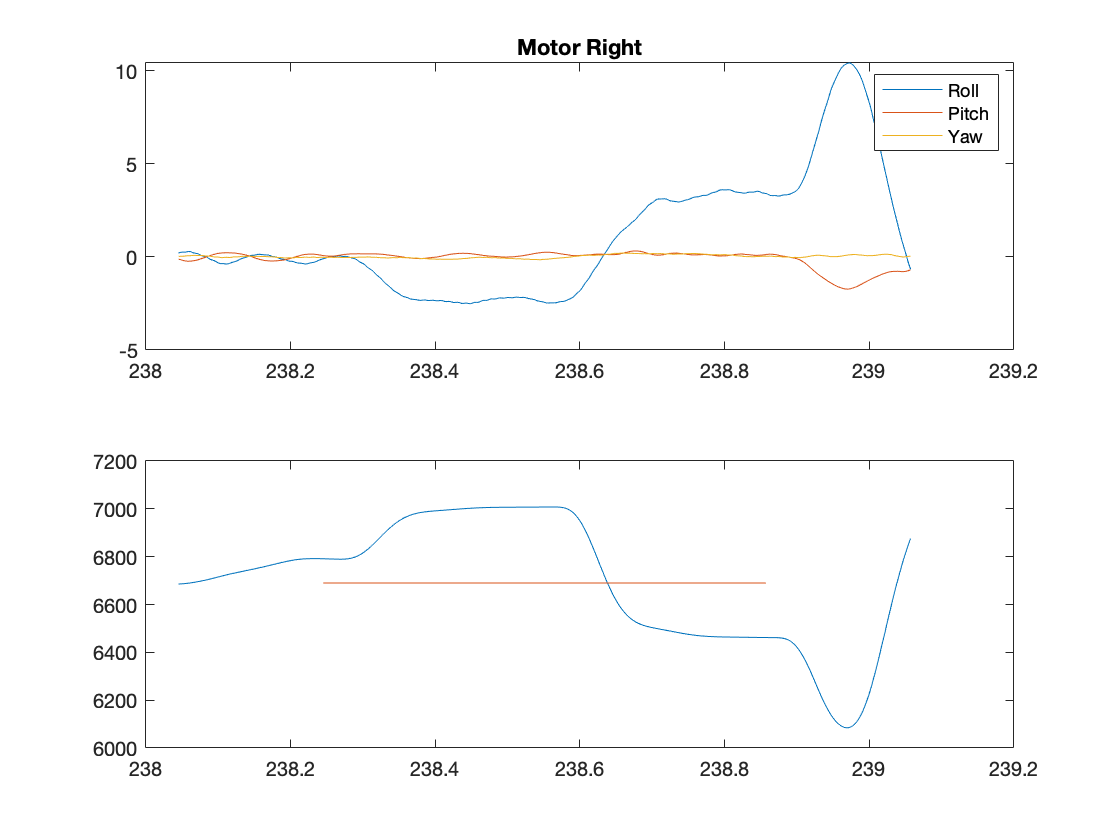

Estimation of effectiveness of actuator Motor Back 


    "ACT"       "-0.00161387"    "-0.00237818"    "0.000288398"
    "OFFSET"    "11.9772"        "17.5692"        "-2.12717"   



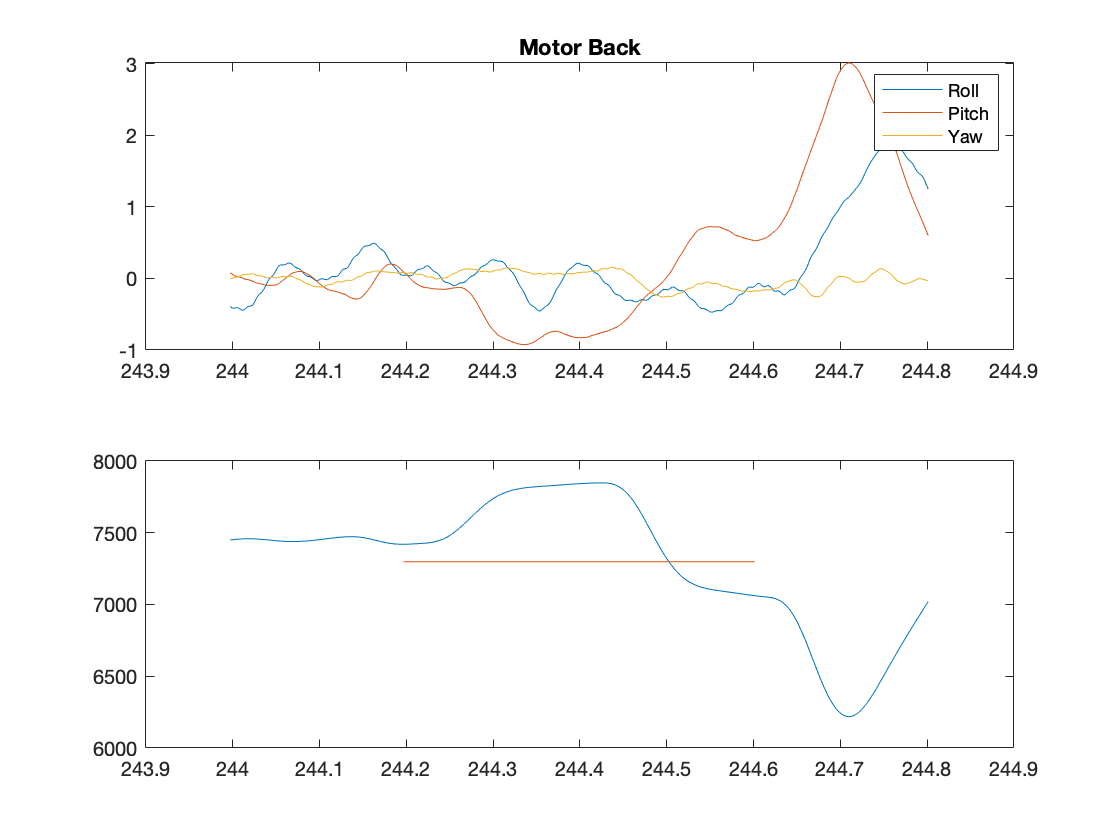

Estimation of effectiveness of actuator Motor Back 


    "ACT"       "0.00421292"    "-0.00222799"    "0.000181584"
    "OFFSET"    "-30.4316"      "16.1354"        "-1.31161"   



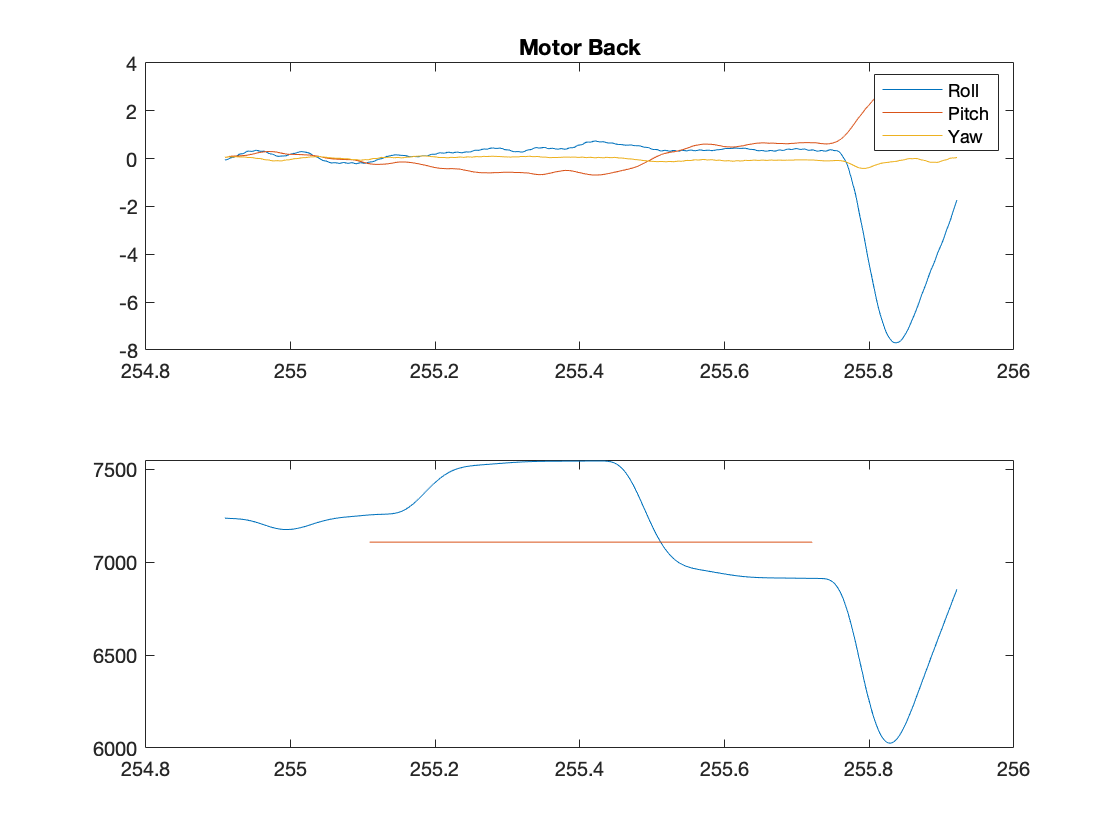

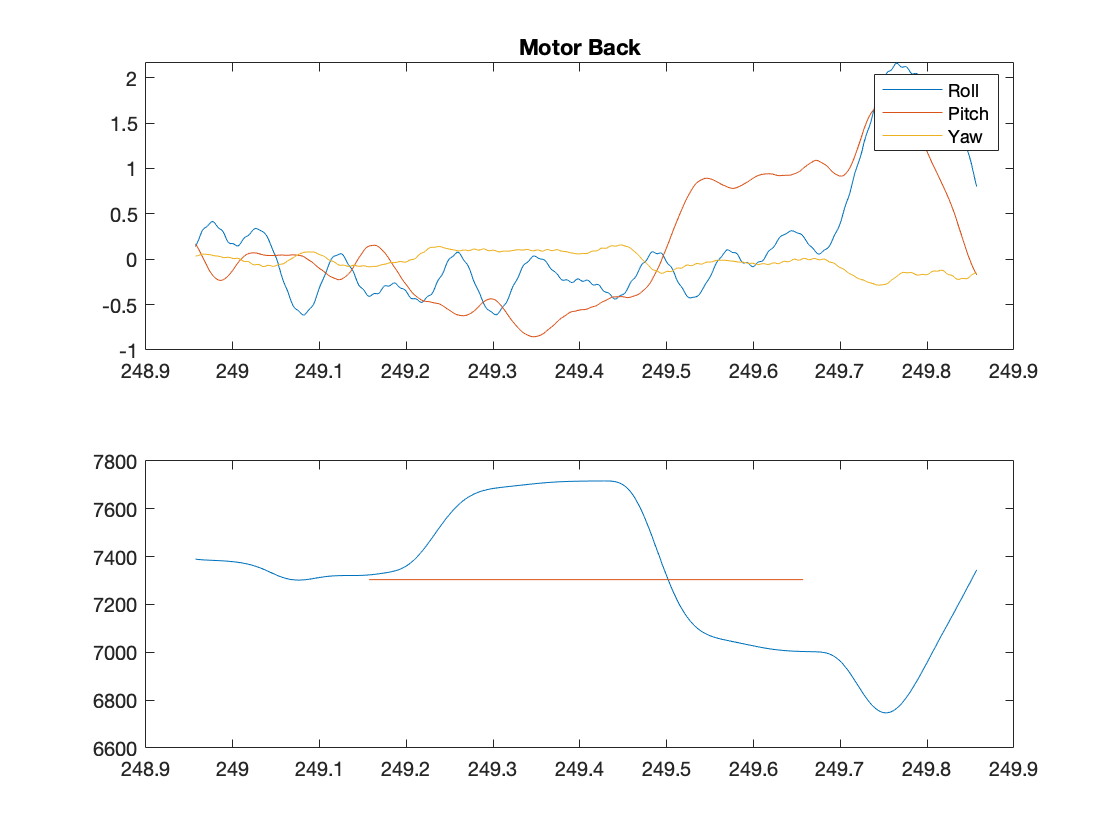

Estimation of effectiveness of actuator Motor Left 


    "ACT"       "0.00934495"    "-0.000714861"    "-0.000310876"
    "OFFSET"    "-64.1583"      "4.93067"         "2.13185"     



Estimation of effectiveness of actuator Motor Left 


    "ACT"       "0.00872673"    "6.44703e-05"    "-0.000489945"
    "OFFSET"    "-61.3582"      "-0.489562"      "3.4256"      



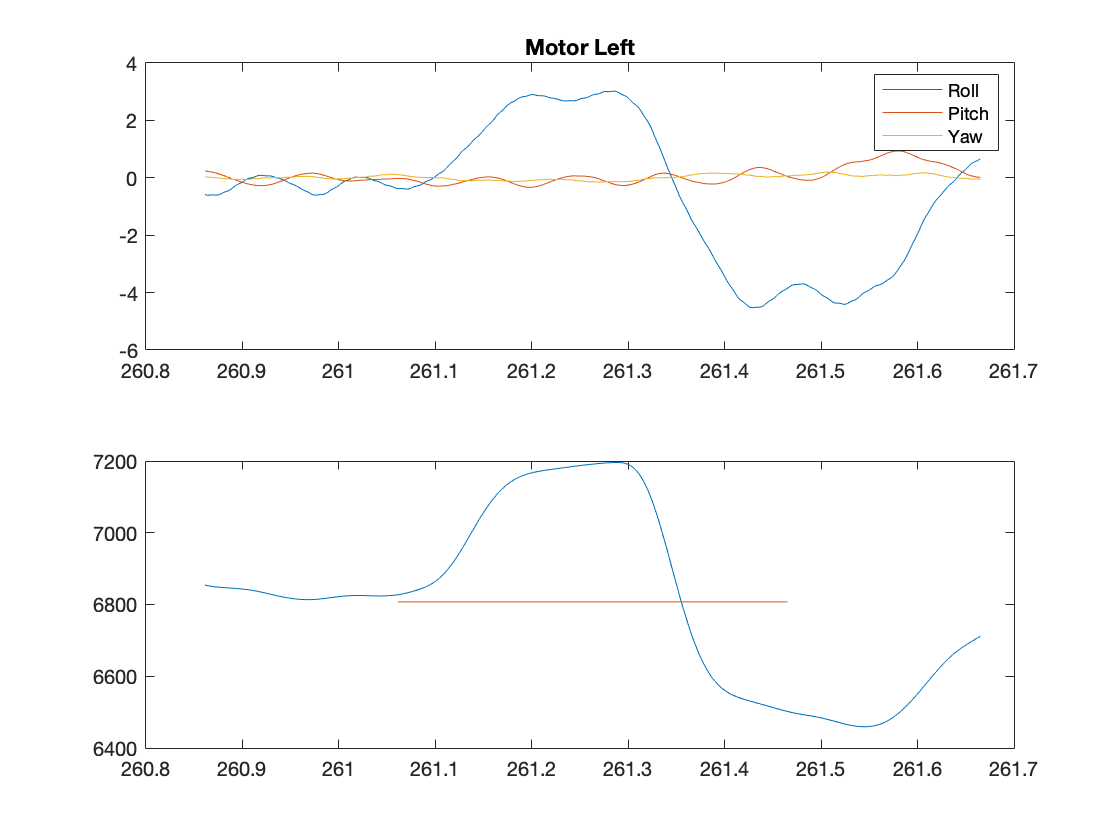

Estimation of effectiveness of actuator Motor Left 


    "ACT"       "0.0108876"    "-7.30985e-05"    "-0.000335805"
    "OFFSET"    "-76.3383"     "0.507046"        "2.35794"     



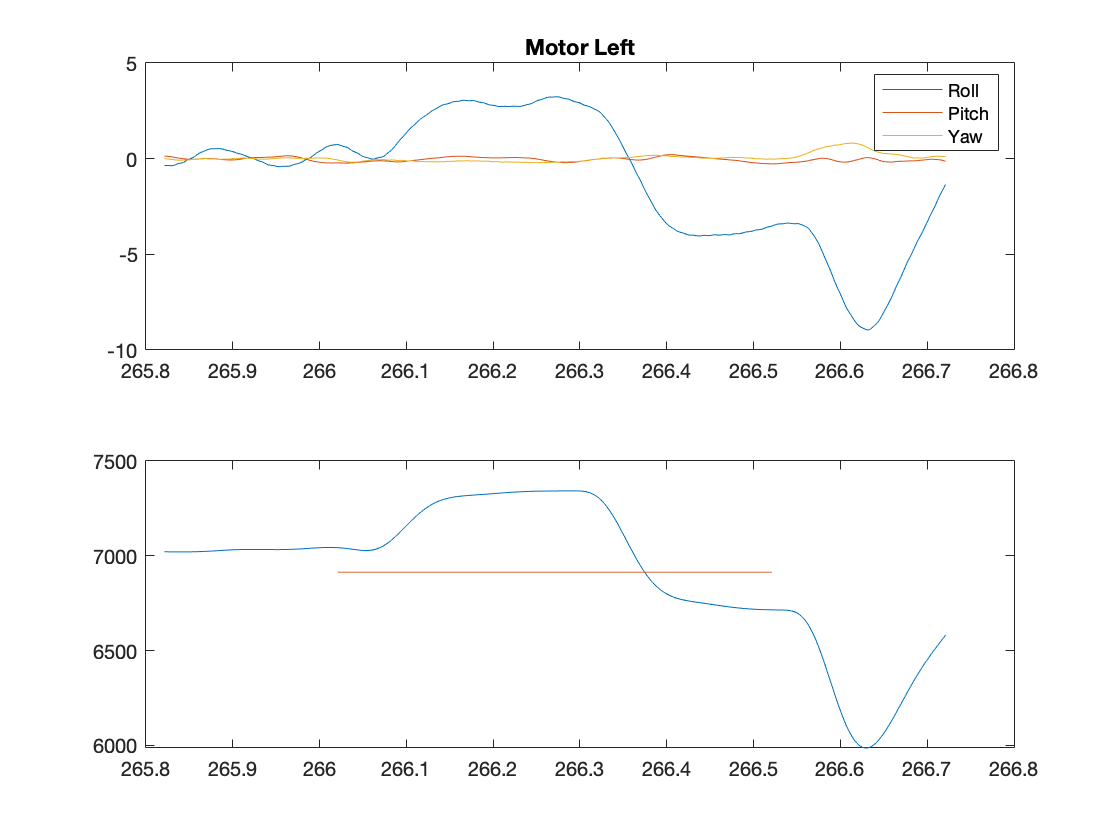

effectiveness_mat =    -0.0016    0.0018    0.0003
   -0.0098    0.0001   -0.0002
   -0.0007   -0.0017    0.0002
    0.0081    0.0002   -0.0002
         0         0    0.0000
         0         0   -0.0000
         0         0    0.0000
         0         0   -0.0000
   27.6670   -3.1830   -1.2215


offset = 0

Approximation routine number: 1


    "Actuator"          "Roll"            "Pitch"          "Yaw"          
    "Motor Front"       "-1.62098914"     "1.80207903"     "0.293868112"  
    "Motor Right"       "-9.84803804"     "0.113968459"    "-0.171511793" 
    "Motor Back"        "-0.669701931"    "-1.68726255"    "0.195931558"  
    "Motor Left"        "8.10906989"      "0.207502407"    "-0.178898848" 
    "Motor Front G2"    "0"               "0"              "0.0121342349" 
    "Motor Right G2"    "0"               "0"              "-0.0172840234"
    "Motor Back G2"     "0"               "0"              "0.0143313231" 
    "Motor Left G2"     "0"               "0"              "-0.0117259845"
    "offset"            "27666.9874"      "-3183.01673"    "-1221.50202"  



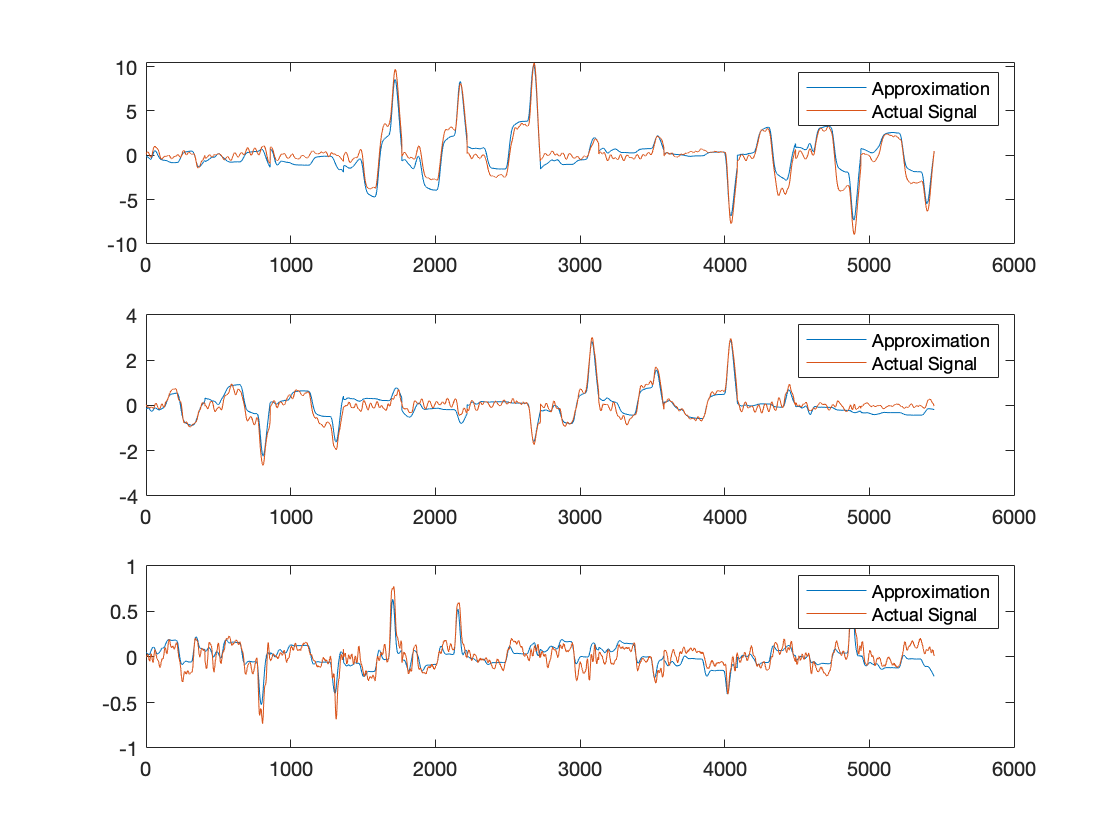

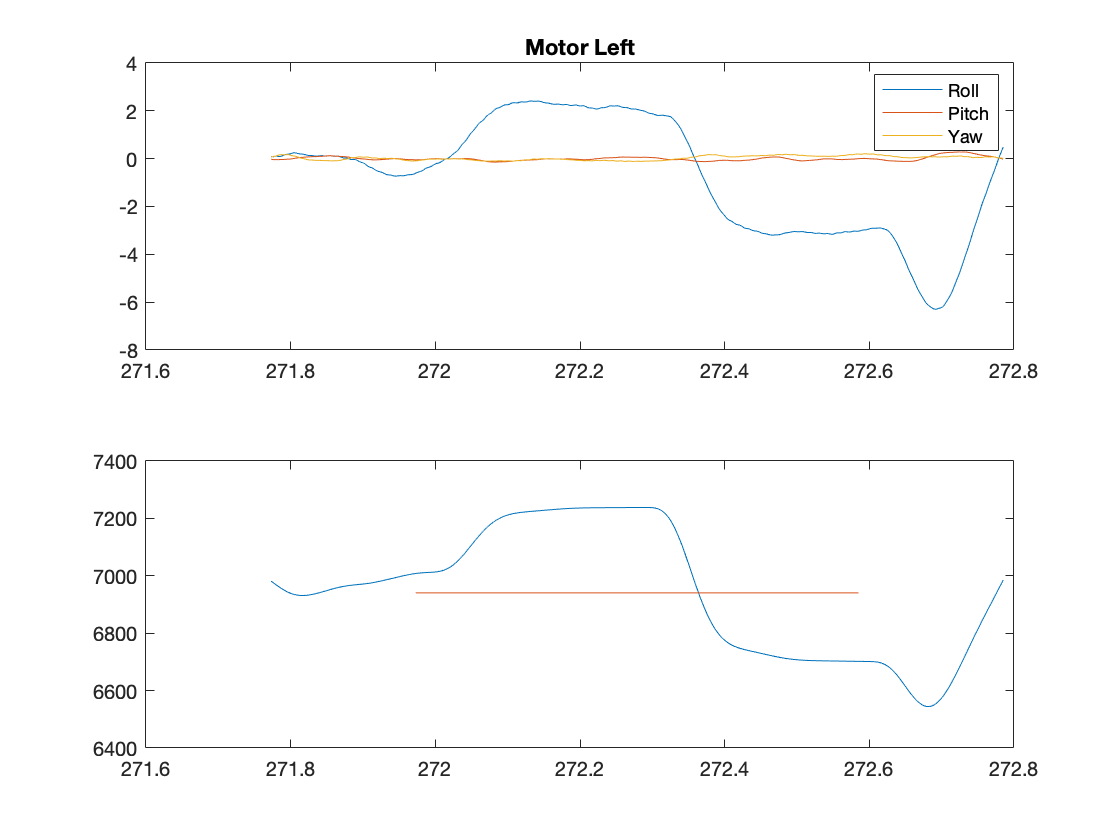

Results      Roll     Pitch    Yaw 


RMSE         0.800851 0.237318 0.090492


RMSE_sigma   0.341335 0.384294 0.588574


RMSE_maxmin  0.041371 0.041948 0.058586



idx_save = [];
save_mat = [];
slack = 0.2;
n_idx = slack*sf;
s_idx = linspace(-1*n_idx,-1,n_idx).';
e_idx = linspace(1,1*n_idx,n_idx).';
doub_numb = 3;
n_m = 12;
debug = 1;
n_wing_sp = 1;
act_num = 4;
for i=1:n_m*n_wing_sp

    n = fix(i/doub_numb)+min(mod(i,doub_numb),1)- 8 * fix(i/(n_m+1));

    idx_range = find((ac_data.EFF_FULL_INDI.doublet_active==1).*(ac_data.EFF_FULL_INDI.doublet_axis==(n-1)).*(ac_data.EFF_FULL_INDI.doublet_number==i));
    range_clean = idx_range;
    idx_range = [idx_range(1)+s_idx;idx_range;idx_range(end)+e_idx];
    idx_save = [idx_save;idx_range];
    
    if debug
            act_aug_d = [act_aug(idx_range,n),act_aug(idx_range,end)];
            acc_d = acc(idx_range,:);
            effectiveness_mat = act_aug_d\acc_d;
            fprintf('Estimation of effectiveness of actuator %s \n',act_names(n))
            disp([["ACT";"OFFSET"],effectiveness_mat])

            figure(i)
            clf
            ax1=subplot(2,1,1);
            plot(t(idx_range),acc_d)
            legend("Roll","Pitch","Yaw")
            title(act_names(n))
            ax2=subplot(2,1,2);
            plot(t(idx_range),act_aug_d(:,1))
            hold on
            plot(t(range_clean),ones(size(t(range_clean))).*mean(act_aug_d(:,1)))
            linkaxes([ax1,ax2],'x');
            hold off
            
    end
  
    if mod(i,n_m) == 0  %perform full estimation 
        act_aug_d = act_aug(idx_save,1:(end-1+augment));
        act_yaw_d = act_yaw(idx_save,1:(end-1+augment));
        acc_d = acc(idx_save,:);
        acc_ld = acc_l(idx_save,:);

        effectiveness_mat = act_aug_d\acc_d(:,1:2);
        effectiveness_yaw = act_yaw_d\acc_d(:,3);
        zero_mat = zeros(4,2);
        effectiveness_mat = [[effectiveness_mat(1:end-1,:);zero_mat;effectiveness_mat(end,:)],effectiveness_yaw]
        magnifying = 1000;
        save_mat = [save_mat,effectiveness_mat];
        math_mat = effectiveness_mat;
        effectiveness_mat = effectiveness_mat * magnifying;
        
        effmat_lin = act_aug_d\acc_ld;
        offset = 0 
        
        %% This logic has to be proved
        if damping
            effectiveness_mat = [[act_names(1:4).';m_d.';act_names(5:8).';"offset";"damp p";"damp q";"damp r"], effectiveness_mat(1:end,:)];
        elseif quad_mode && ~augment
            effectiveness_mat = [[act_names(1:4).';m_d.'], effectiveness_mat(1:end-1,:)];
        elseif quad_mode && augment
            effectiveness_mat = [[act_names(1:4).';m_d.';"offset"], effectiveness_mat(1:end,:)];
        else
            effectiveness_mat = [act_names(1:8).', effectiveness_mat(1:end-1,:)];
        end
        effectiveness_mat = ["Actuator","Roll","Pitch","Yaw";effectiveness_mat];
        
        fprintf('Approximation routine number: %i\n',fix(i/n_m))
        disp(effectiveness_mat)

        approx = act_yaw_d * math_mat;
        figure(200+fix(i/n_m))
        clf
        ax1=subplot(3,1,1);
        plot(approx(:,1))
        hold on
        plot(acc_d(:,1))
        legend("Approximation","Actual Signal")
        
        ax2=subplot(3,1,2);
        plot(approx(:,2))
        hold on
        plot(acc_d(:,2))
        legend("Approximation","Actual Signal")
        
        ax3=subplot(3,1,3);
        plot(approx(:,3))
        hold on
        plot(acc_d(:,3))
        legend("Approximation","Actual Signal")
        linkaxes([ax1,ax2,ax3],'x');
        hold off

        RMSE = sqrt(mean((acc_d - approx).^2));
        RMSE_sigma = RMSE./ std(acc_d);
        RMSE_maxmin = RMSE./ (max(acc_d)-min(acc_d));
        idx_save = [];
        fprintf('Results      Roll     Pitch    Yaw \n')
        fprintf('RMSE         %f %f %f\n',RMSE)
        fprintf('RMSE_sigma   %f %f %f\n',RMSE_sigma)
        fprintf('RMSE_maxmin  %f %f %f\n',RMSE_maxmin)
        
    end
end

% figure(345)
% clf
% plot(t(2:end)-delay_t,acc(:,1))
% hold on 
% plot(t,act_aug * math_mat(:,1))
% legend("actual","approx")
% 

% for j =1:(size(save_mat,2)/3-1)
%     k = j-1;
%     delta_mat = round((save_mat(:,1+j*3:3+j*3)-save_mat(:,1+k*3:3+k*3))./save_mat(:,1+k*3:3+k*3).*100,2);
%     disp("Delta Mat")
%     disp(j)
%     format longG
%     if damping
%         disp(["Actuator","Roll","Pitch","Yaw";[[act_names(1:8).';"offset";"damp p";"damp q";"damp r"],delta_mat]])
%     else
%         disp(["Actuator","Roll","Pitch","Yaw";[act_names(1:8).',delta_mat(1:end-1,:)]])
%     end
%     
% end